# Spring 2024 MAE321 Final Project

**Instructions for the Project:**

- Deadline: Monday, April 29 at 12:45 PM.

- This is an open-book project, but you must work on it independently. You are only permitted to use the lecture notes, the textbook for this course, and Matlab. Any violation of these instructions will result in a grade of zero for the exam and will be reported to the Academic Integrity Office.

- Late submissions will not be graded, resulting in a grade of zero.

- Reminder from the Academic Integrity Office this semester: two level 2 violations or one level 3 violation can lead to a year-long suspension from SU and loss of merit financial aid.

- You MUST use the provided template to answer the first three questions (Question 1 to Question 3) to earn 100 points. Question 4 is a bonus question worth an additional 20 points.

- This exam will NOT be capped at 100 points. The highest possible score is 120.

**Submission Requirements:**

You need to submit two files:

- A single PDF file containing all your solutions. Convert any handwritten solutions to PDF and combine them with the code. To do this, click the arrow under the save command and choose Export to PDF.

- The finished Matlab live script (this file with the extension .mlx). Rename this file using your own NetID as ‘Spring_2024_MAE321_Final_Project_NetID.mlx’.

Honor Pledge:

Sign and date the following honor pledge before beginning:

"I have neither given nor received aid on this examination. I will not use any resources other than the textbook, the lecture notes, and Matlab. I understand any violation of this honor pledge will receive a grade of zero for the exam and will be reported to the Academic Integrity Office."

**name: Teagan Kilian                                                     date: 04/19/2024**

# Question 1: 

### Figure (a) illustrates a dynamometer commonly utilized for vehicle testing.  The vehicle driven by the dynamometer can be simplified to a system depicted in Figure (b), where the wheel can only move vertically while rotating such that $x=r\theta$. ($x$ is measured from the equilibrium position) 

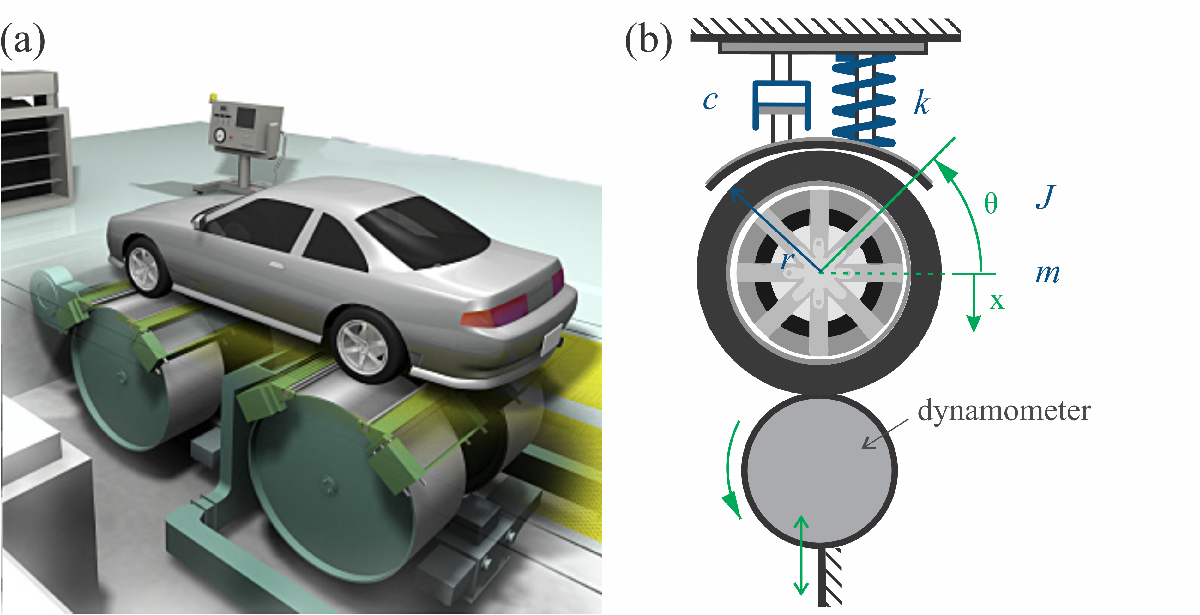

#### 1.1 Derive the equation of motion of this system in terms of vertical displacement *x*. What is the analytical expression for acceleration? 

*You must use the symbolic toolbox to find the expressions; deriving the equations by hand will only get partial credits.*

clc; clear;

% Generalized coordinates...
syms x_s real
X = x_s;
% ... and generalized speeds
syms x_dot real
dXdt = x_dot;
% ... and generalized acceleration
syms x_ddot real
ddXdt = x_ddot;

% Define the necessary parameter subset:
syms m J r k c zeta positive

% Kinetic Energy:         
T = (.5*m*x_dot^2)+(.5*J*(x_dot/r)^2);

% Potential Energy:
V = (.5*k*x_s^2);

% Damping forces:
F_e = -c*x_dot;

% Lagrangian:
L = T-V;
% Partial derivatives:
% step (a) take partial derivative of L w.r.t dXdt
dLdXdt = jacobian(L,dXdt).';
% step (b) use the chain rule and take the partial derivative w.r.t t
dL_dXdt_dt = jacobian(dLdXdt,dXdt)*ddXdt.' + jacobian(dLdXdt,X)*dXdt.';
% step (c) take partial derivative of L w.r.t X
dLdX   = jacobian(L,X).';

% Apply Euler-Lagrange equation
EOM = dL_dXdt_dt - dLdX - F_e == 0

$$EOM = \ddot{x}\,\left(m+\frac{J}{r^{2}}\right)+c\,\dot{x}+k\,x_{s}=0$$


% Compute the acceleration:
x_ddot = solve (EOM, ddXdt)

$$x\_ddot = -\frac{c\,\dot{x}+k\,x_{s}}{m+\frac{J}{r^{2}}}$$

#### 1.2 Assume in this system *k* = 10 kN/m, *m* = 12 kg, *r* = 340 mm, and *J* = 0.016 kg m^2. What is the range of values for the dashpot coefficient *c* you can select for the suspension system to ensure the system is underdamped?

% effective mass
m_eff = m+(J/r^2);

% plug in system parameters
k_val = 10000; % N/m 
m_val = 12; % kg
r_val = .340; %m
J_val = 0.016; %kg m^2

d_r = c/(2*sqrt(k*m_eff)) == zeta

$$d\_r = \frac{c}{2\,\sqrt{k}\,\sqrt{m+\frac{J}{r^{2}}}}=\zeta$$


% solve for damping coefficient 
c = solve(d_r, c);

% sub values 
c1 = subs(c, m, m_val);
c2 = subs(c1, k, k_val);
c3 = subs(c2, r, r_val);
c4 = subs(c3, J, J_val);

% macimum damping 
zeta_max = 1;
c_max = vpa(subs(c4, zeta, zeta_max),4)

$$c\_max = 696.8$$


% minimum damping 
zeta_min = 0;
c_min = subs(c4, zeta, zeta_min)

$$c\_min = 0$$

#### 1.3 Use the following settings and simulate the motion of the system due to the initial condition $x_o =3$ cm and $v_0 =-20\;$cm/s. Plot the results for 5 seconds and determine the smallest value of the damping coefficient *c* you can select (round it up to an integer value) such that the amplitude of the wheel oscillation will be smaller than 1 cm and the velocity will be bounded to 0.3 m/s after 1 second.

% find the damping coefficient using the plot below (use the figure to do trial and error):
c_num = 33

c_num = 33

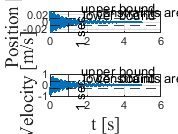


% define the time interval and the number of integration steps
n    = 10000; 
t    = zeros(n,1);
tf   = 5;
t(1) = 0;
delt = (tf-t(1))/n;

% initializing variables
x   = zeros(n,1);
v   = zeros(n,1);

% assign initial conditions (be careful of the units)
x(1) = .03; % m     
v(1) = -.2; % m/s

% start the integration directly from the second step (with i=2)
for i=2:1:n
    % update the velocity and acceleration for x at step i 
    dx = v(i-1) ;
    dv = -((c_num*dx)+(k_val*x(i-1)))/(m_val+(J_val/r_val^2)) ;
    
    % integrate x and v
    x(i) = x(i-1) + delt* dx;
    v(i) = v(i-1) + delt* dv;
    
    % integrate time
    t(i) = t(i-1) + delt ;
    
end % end of each integration step  

% plot results 
figure(10)
clf; 

% plot position
subplot(2,1,1) 
box on; grid on; hold on;
plot(t,x,'linewidth',2);
ylabel('Position [m]', 'fontsize', 14, 'fontname', 'times');

% find the indices of all elements that are smaller or equal to 1
time_flag = (t<=1);
% find the index of the last element 
time_ind = find(time_flag,1,'last');

% Check the constraint violation for position:
if all(abs(x(time_ind:end))<0.01)
    yline(0.01,'k--','upper bound');
    yline(-0.01,'k--','lower bound');
    text(2.5,0.03,'constraints are satisfied');
else
    yline(0.01,'r--','upper bound');
    yline(-0.01,'r--','lower bound');
    text(2.5,0.03,'constraints are violated');
end
xline(1,'k--','1 sec');

% plot velocity
subplot(2,1,2) 
box on; grid on; hold on;
plot(t,v,'linewidth',2);
xlabel('t [s]', 'fontsize', 14, 'fontname', 'times');
ylabel('Velocity [m/s]', 'fontsize', 14, 'fontname', 'times');   

% check constraint violation for speeds
if all(abs(v(time_ind:end))<0.3)
    yline(0.3,'k--','upper bound');
    yline(-0.3,'k--','lower bound');
    text(2.5,0.7,'constraints are satisfied');
else
    yline(0.3,'r--','upper bound');
    yline(-0.3,'r--','lower bound');
    text(2.5,0.7,'constraints are violated');
end
xline(1,'k--','1 sec');

Your result from 1.3 should look like this:

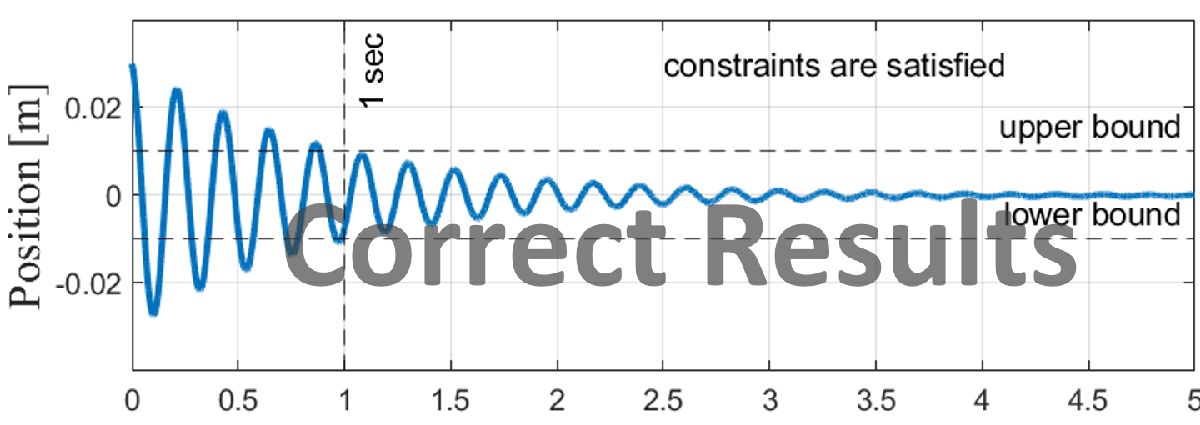

# Question 2: 

### Suppose you are driving a car over a wavy road as illustrated in the figure below. The mass of the wheel compared with the whole vehicle is negligible, and the mass of the car supported by a single wheel is 331 kg. The suspension system has a stiffness of 10 kN/m and a damping coefficient of 50 kg/s. 

### 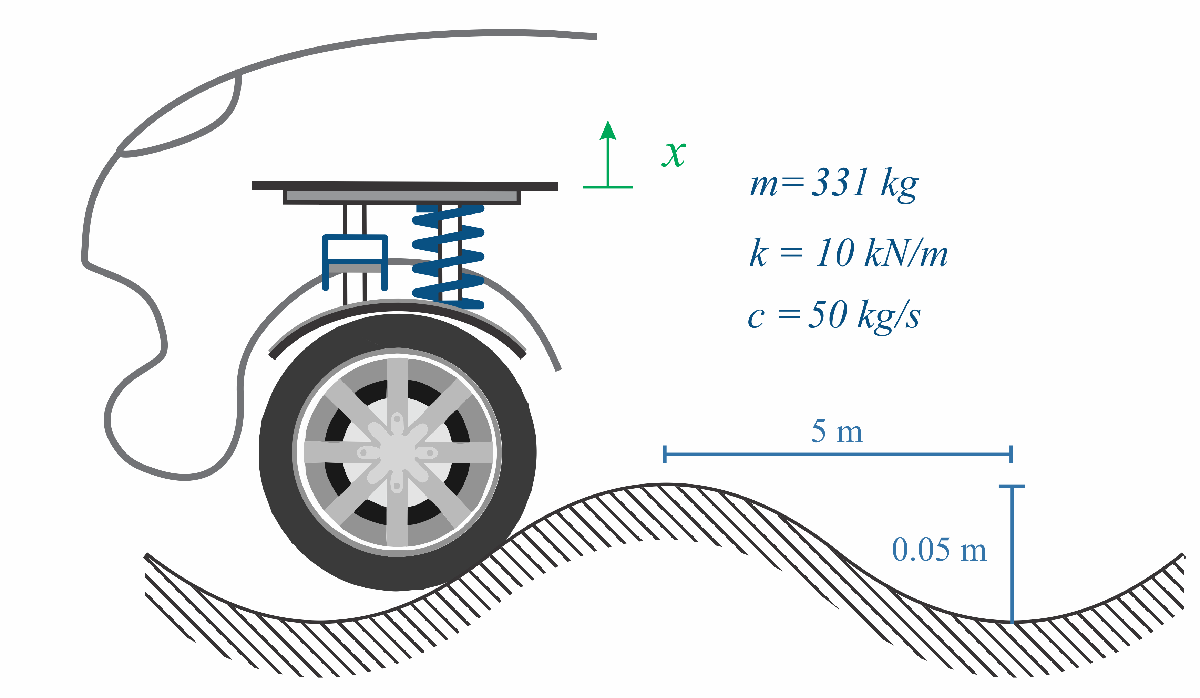

#### 2.1 Suppose the wheel maintains solid contact with the ground at all times without slipping motion. When the car is driven at 65 miles per hour, determine the vertical position of the wheel as a function of time $x\left(t\right)$. (Hint: refer to Example 2.4.2 in textbook)

clc; clear;

syms t x0 v0 positive

% define system parameters:
c    = 50               ;% kg/s
k    = 10000            ;% N/m
m    = 331              ;% kg
zeta = c / (2*sqrt(k*m));
omega_n = sqrt(k/m)     ;
omega_d = omega_n*sqrt(1-zeta^2);

 if zeta < 1
    system = 'underdamped'
 end

system = 'underdamped'

 if zeta > 1
  system = 'overdamped'
 end

% define base motion
wl    = 10    ;% m 
Y     = .05/2   ;% m
speed = 65    ;% mph
v     = speed*1609.3/3600 ;% m/s
omega_b = v*2*pi/wl ;   

r = omega_b / omega_n ;
% base excitation formula

y   = Y*sin(omega_b*t);

A1  = (v0 + (zeta*omega_n*x0)) / omega_d;
A2  = x0;

theta_1 = atan((2*zeta*omega_n*omega_b)/((omega_n^2 - omega_b^2)));
theta_2 = atan(omega_n/(2*zeta*omega_b));

X   =  Y * sqrt((1+(2*zeta*r)^2)/((1-r^2)^2 + (2*zeta*r)^2));

x_h = exp(-zeta*omega_n*t)*((A2*cos(omega_b*t)) + (A1*sin(omega_b*t)));

x_p = X * cos((omega_b*t) - theta_1 - theta_2);

x = x_h + x_p;

x = vpa(x,3)

$$x = 0.0025\,\cos\left(18.3\,t-1.47\right)+{\mathrm{e}}^{-0.0755\,t}\,\left(x_{0}\,\cos\left(18.3\,t\right)+\sin\left(18.3\,t\right)\,\left(0.182\,v_{0}+0.0137\,x_{0}\right)\right)$$

#### 2.2 Suppose zero initial conditions, simulate the system for 10 seconds using the settings provided below.

% define system parameters:

c = 50      ;% kg/s
k = 10000   ;% N/m
m = 331     ;% kg

% define equation of motion 
syms x x_dot x_ddot positive

EOM_L = m*x_ddot + c*x_dot + k*x;
EOM_R = c*Y*omega_b*cos(omega_b*t) + k*Y*sin(omega_b*t);

EOM = EOM_L == EOM_R;
EOM = vpa(EOM,3)

$$EOM = 1.0e+4\,x+50.0\,\dot{x}+331.0\,\ddot{x}=22.8\,\cos\left(18.3\,t\right)+250.0\,\sin\left(18.3\,t\right)$$

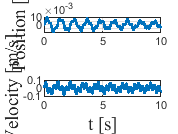


% define the time interval and the number of integration steps
n    = 100000; 
t    = zeros(n,1);
tf   = 10;
t(1) = 0;
delt = (tf-t(1))/n;


% initializing variables
x    = zeros(n,1);
v    = zeros(n,1);

% assign initial conditions
x(1) = 0 ;
v(1) = 0 ;


% start the integration directly from the second step (with i=2)
for i=2:1:n
    % update the velocity and acceleration for x at step i 
    dx = v(i-1) ;
    dv = (c*Y*omega_b*cos(omega_b*t(i-1)) + k*Y*sin(omega_b*t(i-1))- c*dx - k*x(i-1))/m;
    
    % integrate x and v
    x(i) = x(i-1) + dx * delt ;
    v(i) = v(i-1) + dv * delt ;
    
    % integrate time
    t(i) = t(i-1) + delt ;
    
end % end of each integration step  

% plot results 
figure(20)
clf; 
% plot vertical position
subplot(2,1,1) 
box on; grid on; hold on;
plot(t,x,'linewidth',2);
ylabel('Position [m]', 'fontsize', 14, 'fontname', 'times');
% plot vertical velocity
subplot(2,1,2) 
box on; grid on; hold on;
plot(t,v,'linewidth',2);
xlabel('t [s]', 'fontsize', 14, 'fontname', 'times');
ylabel('Velocity [m/s]', 'fontsize', 14, 'fontname', 'times');   

#### 2.3 Analytically determine the oscillation amplitude of the vehicle. Does this value match with your simulation result from the previous question and why?

X   =  Y * sqrt((1+(2*zeta*r)^2)/((1-r^2)^2 + (2*zeta*r)^2))

X = 0.0025


% The amplitude 'X' represents the steady-state amplitude of the system,
% because the simulation does not run long enough to produce the steady
% state, the amplitude value of 0.0025 does not seem to appear. However, if
% the simulation is run long enough so that the transient response settles
% and the steady state response is the only response that remains, the
% oscillation amplitude of the vehicle will be X. 


# Question 3: 

### Another automobile is approaching an elevated road at a constant speed of 45 miles per hour. At time *t*=0, it is 25 meters away from the step. The elevated road is 5 cm higher than the level of the current road surface, as shown below.

### 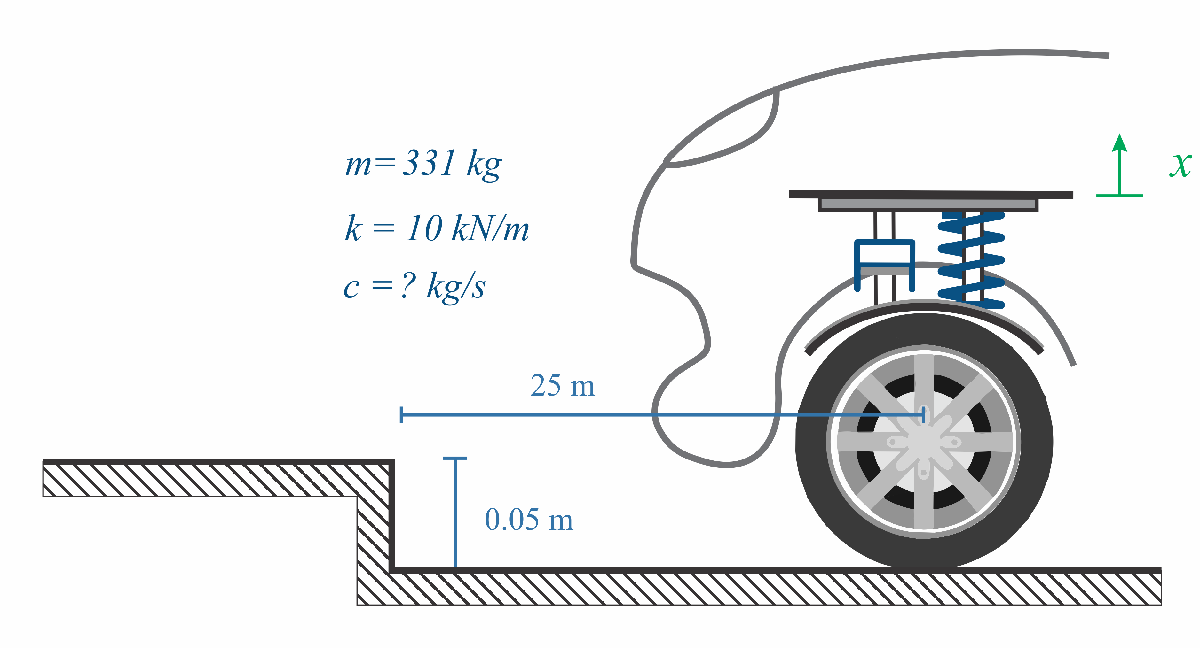

#### 3.1 When will the vehicle run over the step? How much force will be applied to the vehicle due to the step? Plot the force profile provided by the elevated road as a function of time. 

clc; clear;

% define system parameters 
delx   = 0.05  ; % m
m   = 331   ; % kg
k   = 10000 ; % N/m

omega_n = sqrt(k/m);

% convert to m/s
speed = 45  ; % mph
v1    = speed*1609.3/3600 ;% m/s
dist  = 25   ; % m

% find time of impact 
tau = dist / v1  % s

tau = 1.2428

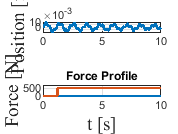


F_tau = k * delx  ; % N

t = 0:.01:10 ; 

F = F_tau*heaviside(t - tau);

plot(t,F,'linewidth',2);
ylim ([0,700])
xlabel('t [s]', 'fontsize', 14, 'fontname', 'times');
ylabel('Force [N]', 'fontsize', 14, 'fontname', 'times');   
title 'Force Profile'

#### 3.2 Suppose zero initial conditions, simulate the system for 10 seconds using the settings provided below and determine what is the smallest damping coefficient value you can use to make the settling time smaller than 3 seconds.

Settling time is defined how long it takes the perturbed system to return within 3% of the steady state value. Round the damping coefficient value up to an integer number. 

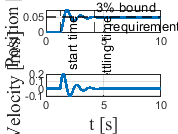

% find the damping coefficient using the plot below:
c = 776 ; % kg/s

zeta    = c/(2*sqrt(k*m));
omega_d = omega_n*sqrt(1-zeta^2);

syms t positive 
% unit impulse response 
h = 1/m/omega_d*exp(-zeta*omega_n*(t-tau))*sin(omega_d*(t-tau));

syms x x_dot x_ddot positive 
EOM_L = m*x_ddot + c*x_dot + k*x;
EOM_R = F;

EOM = EOM_L == EOM_R;

% define the time interval and the number of integration steps
n    = 100000; 
t    = zeros(n,1);
tf   = 10;
t(1) = 0;
delt = (tf-t(1))/n;

% initializing variables
x    = zeros(n,1);
v    = zeros(n,1);
% assign initial conditions
x(1) = 0;
v(1) = 0;

% start the integration directly from the second step (with i=2)
for i=2:1:n
    % update the velocity and acceleration for x at step i 
    dx = v(i-1) ;
    dv = (F_tau*heaviside(t(i-1) - tau) - c*dx - k*x(i-1))/m;
    
    % integrate x and v
    x(i) = x(i-1) + dx*delt;
    v(i) = v(i-1) + dv*delt;
    
    % integrate time
    t(i) = t(i-1) + delt;
    
end % end of each integration step  

% plot results 
figure(31)
clf; 
% plot position
subplot(2,1,1) 
box on; grid on; hold on;
plot(t,x,'linewidth',2);
ylabel('Position [m]', 'fontsize', 14, 'fontname', 'times');

% check the constraint violation:
% flag all values violate the requirement
violated_flag = abs(x-0.05)>0.05*0.03;
% find the index of the last violated element
vio_ind = find(violated_flag,1,'last');
% calculate settling time
ts = t(vio_ind) - tau;

if ts<3 % if settling time is smaller than 3 seconds
    yline(0.05*(1+0.03),'k--','3% bound');
    yline(0.05*(1-0.03),'k--');
    text(5.5,0.025,'requirements are satisfied');
else % if settling time is bigger or equal to 3 seconds
    yline(0.05*(1+0.03),'r--','3% bound');
    yline(0.05*(1-0.03),'r--');
    text(5.5,0.025,{'requirements are violated,', ...
        ['current settling time is ',num2str(ts)]});
end
xline(tau,'k--','start time');
xline(t(vio_ind),'k--','settling time');

% plot velocity
subplot(2,1,2) 
box on; grid on; hold on;
plot(t,v,'linewidth',2);
xlabel('t [s]', 'fontsize', 14, 'fontname', 'times');
ylabel('Velocity [m/s]', 'fontsize', 14, 'fontname', 'times');  

Your result from 3.2 should look like this:

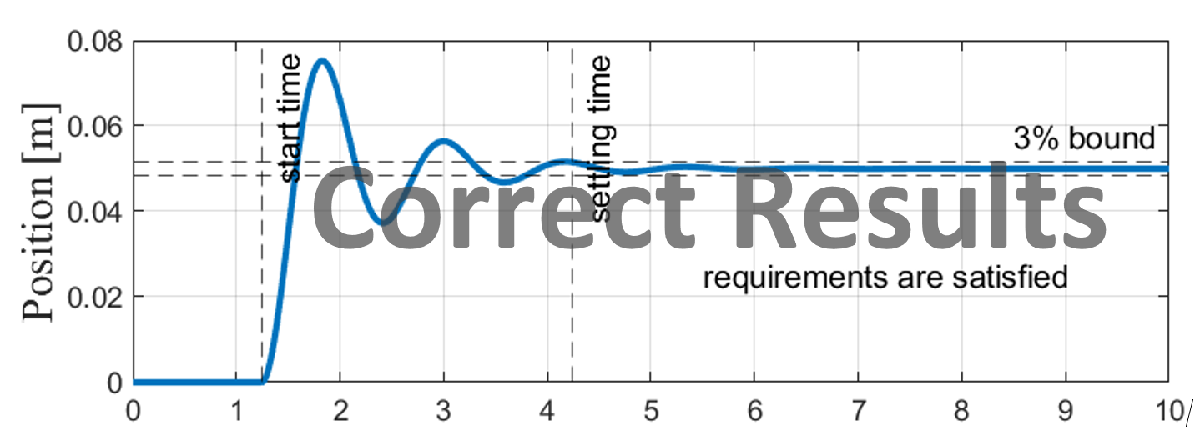

#### 3.3 Find the analytical solution of the vehicle position and velocity and plot it against the simulation result. 

% define symbolic time variable
syms ts positive

 if zeta < 1
    system = 'underdamped'
 end

system = 'underdamped'

 if zeta > 1
  system = 'overdamped'
 end

% analytical solution of x as a function of ts 

theta = atan(zeta/(sqrt(1-zeta^2))) ; 

x_a = ((F_tau/k) - (F_tau/(k*sqrt(1-zeta^2)))*exp(-zeta*omega_n*(ts-tau))*cos(omega_d*(ts-tau)-theta))*heaviside(ts-tau);
x_a = vpa(x_a, 3)

$$x\_a = -1.0\,\mathrm{heaviside}\left(1.0\,\mathrm{ts}-1.24\right)\,\left(0.0512\,\cos\left(5.37\,\mathrm{ts}-6.89\right)\,{\mathrm{e}}^{1.46-1.17\,\mathrm{ts}}-0.05\right)$$

v_a = diff(x_a, ts);
v_a = vpa(v_a, 3)

$$v\_a = 1.0\,\mathrm{heaviside}\left(1.0\,\mathrm{ts}-1.24\right)\,\left(0.275\,{\mathrm{e}}^{1.46-1.17\,\mathrm{ts}}\,\sin\left(5.37\,\mathrm{ts}-6.89\right)+0.06\,\cos\left(5.37\,\mathrm{ts}-6.89\right)\,{\mathrm{e}}^{1.46-1.17\,\mathrm{ts}}\right)-1.0\,\delta (\mathrm{ts}-1.24)\,\left(0.0512\,\cos\left(5.37\,\mathrm{ts}-6.89\right)\,{\mathrm{e}}^{1.46-1.17\,\mathrm{ts}}-0.05\right)$$

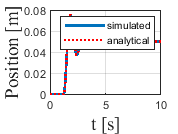


figure(32)
clf
box on; grid on; hold on;
plot(t,x,'linewidth',2);
xlabel('t [s]', 'fontsize', 14, 'fontname', 'times');
ylabel('Position [m]', 'fontsize', 14, 'fontname', 'times');

fplot(ts,x_a,[0,10],'r:','linewidth',2);
legend('simulated','analytical')